# P06: Sistemas de inferencia difusos (FIS)

## Objetivos

- Implementar sistemas de inferencia difusos, utilizando MATLAB

- Decodificar sistemas de inferencia difusos implementados en Simulink

## Entregables

Se revisa una publicación (html) de la práctica. En este caso tendá que iniciar indicando el nombre de la práctica y sus datos personales, equipos de 3 a 5 personas (Portada). El índice lo genera MATLAB. Los objetivos deben ser incluidos y se han presentado al principio de la práctica.

Como introducción describe el modelo difuso de inferencia de Tsukamoto. Puedes apoyarte de las referencias que consideres necesarias. Los datos del trabajo orignal son:

**T. Tsukamoto.** *An approach to fuzzy reasoning method*. In Madan M. Gupta. Ramohan K. Ragade, and Ronal R. Yager, editors, *Advance in fuzzy set theory and applications*, pages 137-149. North-Holland, Amsterdam, 1979

Para el desarrollo se tienen que resolver los siguientes problemas. Se comienza una nueva sección (para la publicación) en cada uno.

### Problema 1

 La herramienta **Fuzzy Logic Toolbox (FLT)**, Cuenta con una interfaz de gráfica de diseño de sistemas de inderencia difusos

fuzzyLogicDesigner()

Para conecer el uso de esta interfaz se puede consultar la implentación del **problema de la propina **(problema de un sistema con dos entradas y una salida). La implementación es mediante la inferencia tipo Mandani. Para consultar dicha implementación puedes revisar el siguiente enlace: [Build Fuzzy Systems Using Fuzzy Logic Designer](https://www.mathworks.com/help/fuzzy/building-systems-with-fuzzy-logic-toolbox-software.html)

El problema  a desarrollar consistenen hacer uso de la herramienta gráfica para construir un sistema de inferencia difuso tipo Mandani. El problema es una variante del problema de la propina. Las condiciones son las siguientes

- 2 entradas (servicio y comida)

- El universo de discuros de ambas variables lingüisticas es $[0,100]$

- 1 salida (propina)

- El universo de discurso de esta variable lingúistica es [0,15] 

- Cada variable lingúistica dene tener por lo menos cuatro valores lingúisticos. Por lo menos un valor lingúistico debe ser una variación de un primitivo (por ejemplo: muy rica).

- La semantica de cada variable lingüista se deja a su *"experiencia como consumidor"*

- Se tienen que proponer por lo menos cuatro reglas si - entones, para la inferencia difusa (se tiene que utilizar por lo menos una vez cada conjunto difuso propuesto en su semántica)

En el desarollo se espera el planteamiento del problema a resolver, así como documentar la construcción correspondiente (parecido a lo presentado en el enlace anterior)

¿Existe una situación donde el problema usual tenga "mal desempeño" al compararlo con tu implementación?

¿Existe una situación donde el problema usual tenga "mejor desempeño" al compararlo con tu implementación?

### Problema 2

La impletación en Simulink de un FIS para aplicaciones de control,  se realiza principalmente con los siguientes bloques:

- [Fuzzy Logic Controller](https://www.mathworks.com/help/fuzzy/fuzzylogiccontroller.html) (FLC)

- [Fuzzy Logic Controller with Ruleviewer](https://www.mathworks.com/help/fuzzy/fuzzylogiccontrollerwithruleviewer.html) (FLCR)

El funcionamiento de los bloques sigue el principio de Simulink, se conectan las entradas, se procesan y se generan las salidas. En cada bloque basta indicar el nombre del sistema FIS. Este puede ser construido con el fuzzyLogicDesigner y exportado al workspace. También puede ser contruido mediante alguna de las posibles alternativas de código.

Exiten dos diferencias principales entre ambos bloques. El primero se puede asociar a  diferentes sistemas de inferencia, mientras el segundo, solo puede ser asociado a un FIS tipo Mandami o Sugeno, pero con la ayuda visual del RuleViewer (descrito en el enlace del problema 1). 

Para explorar  la implentación de los FIS en Simulink. Se trabajará con el control de nivel de agua en un tanque. 

Se tiene la siguiente implementación en Simulink

open_system('sltank')

La instrucción anterior abre el ejemplo antes mencionado. En particular se genera en el workspace la variable **tank** tipo *mamfis* (Sistema de inferencia difuso tipo Mamdani)

tank

tank =   mamfis with properties:

                       Name: "tank"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×5 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


Este FIS es el que se encuentra asociado al bloque FLC. Puedes explorar esta simulación de acuerdo a lo descrito en el siguiente enlace: [Water Level Control in a Tank](https://www.mathworks.com/help/fuzzy/water-level-control-in-a-tank.html). Puedes explorar el FIS de varias maneras, para hacerlo con la app 

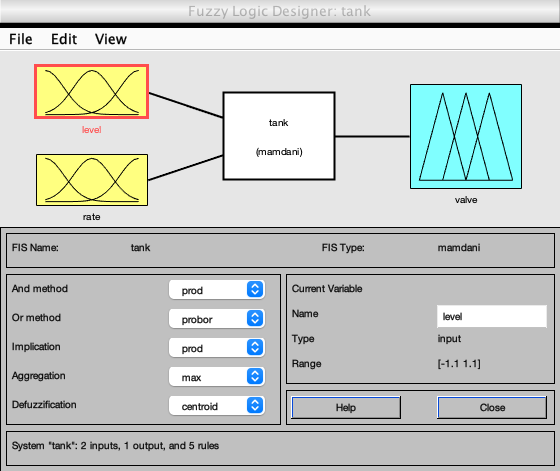

fuzzyLogicDesigner(tank)

Con apoyo de lo anterior, contesta lo siguiente

**2.1** ¿Cuántas variables lingúistcas se tienen?

**2.2** ¿Cuál es el universo de discurso de cada una?

**2.3** Grafica las conjuntos difusos de cada variable lingüistica

**2.4** Muestra las reglas de inferencia difusa utilizadas

**2.5** Explica en que consiste la implementación del sistema (una descripción general de todos bloques) en especial los bloque de visualización, así como la simulación mostrada 

### Problema 3

La logica difusa se puede implementar en varias aplicaciones en ingeniería, tal es el caso de:

**Hela Lassoued, Raouf Ketata**, *Chapter 5 - Genetic fuzzy logic based system for arrhythmia classification*, Editor(s): Olfa Boubaker, Control Theory in Biomedical Engineering, Academic Press, 2020, Pages 105-127, ISBN 9780128213506. [Enlace](https://www.sciencedirect.com/science/article/pii/B9780128213506000056)

Contesta las siguentes preguntas respecto a la revisión del documento

**3.1** ¿Qué factores explican la presencia de arritmias?

**3.2** ¿A qué se refieren las siglas DSS?

**3.3** ¿A qué se refieren las siglas FLC?

**3.4** ¿A qué se refieren las siglas GA?

**3.5** ¿Cuál es el principal objetivo del capítulo 5?

**3.6**  La base de datos  *MIT-BIH Arrhythmia Database* contine varios registros de distintos tipos de arritmias, ¿Cuáles son estos?   

**3.7** ¿De que depende el desempeño de un  FLC?

**3.8** ¿Para que utilizan un GA?

**3.9** La Figura 1 muestra un diagrama de bloques de la metodología implementada para la clasificación de arritmias. En nuestro caso nos interesa el bloque de clasificación. Este está compuesto por configuración y optimización. ¿En que consisten las entradas (input features) que recibe este bloque de clasificación? 

**3.10** La principal ventaja de un FLC es que no es necesario un modelo matemático para la implementación del controlador (difuso). En general esto es el caso (como en el ejemplo del Problema 2), aunque puede suceder que para resolver cierta clase de problemas  sea necesario el modelo matemático de un subsistema. Se espera que la Figura 10 sea transparente en este momento. De acuerdo al texto ¿Cuál es la diferencia entre la inferencia de Mamdani y Sugeno?

**3.11** De la sección 2.2.1 FLC configuration, ¿Cuántas variables lingüisticas se tienen? ¿Quñe tipo de conjuntos difusos son los conecuentes? ¿Cuantas reglas si-entones se proponen? ¿Que sistemas de inferencia se utiliza?   ¿Qué operaciones se utilizan para la Conjunción, Disyunción e Implicación?

**3.12** Reporte el diagram de flujo del GA utilizado.

**3.13** Escriba la expresión matemática para la  *fitness function*  utilizada

**3.14** No se pretende profundizar sobre el funcionamiento del GA. Basta con tener una visión general de su uso en esta implementación, En particular los parametros a optimizar se les da el nombre de *cromosomas. *En este caso ¿Qué representan los cromosomas? ¿Cuáles son los resultados del proceso de optimización?

**3.15** ¿Cuáles fueron los resultados de la implementación?

Este trabajo hace uso de la logica difusa para resolver un problema de clasificación, que es una de las varias aplicaciones de la lógica difusa. 

*No es necesario incluir conclusiones en esta práctica, si lo consideras necesario puedes incluir apéndices (en caso que estos no se pidan explicitamente), no olvides incluir tus referencias. *